# Proyecto Global de Asignatura

## Rubén A. y David A. - Otoño 2024

clear;
decimales =4;
muestras_para_media = 50;
aproximacion = -3;

### Fase 1 - Caracterización de la planta

**Ejercicio 1**

Capture y caracterice la salida de la planta en función de la tensión de entrada con un  procedimiento análogo al empleado en la Práctica 2 y obtenga su función de transferencia  (FdeT) en las unidades que considere más adecuadas para trabajar en el desarrollo de todo  el diseño. 

escalon_sin_perturbacion = load("Fase1/escalon_sin_perturbacion");
Ts = 35e-3;

tiempo     = escalon_sin_perturbacion(:, 1);
referencia = escalon_sin_perturbacion(:, 2);
salida     = escalon_sin_perturbacion(:, 3);

x_ini = find(referencia > 0, 1, 'first');
x_fin = length(referencia);

t_ini = tiempo(x_ini);
t_fin = tiempo(end);

t_interes = tiempo(x_ini:x_fin) - tiempo(x_ini);
c_interes = salida(x_ini:x_fin);

fprintf("Valor final de respuesta al escalón")

Valor final de respuesta al escalón

c_inf = mean(c_interes(end-muestras_para_media, end))

c_inf = 0.1910


fprintf("Valores de tiempo de establecimiento")

Valores de tiempo de establecimiento

ks = find(c_interes >= 0.95*c_inf, 1, 'first') - 1

ks = 23

ts = ks*Ts

ts = 0.8050

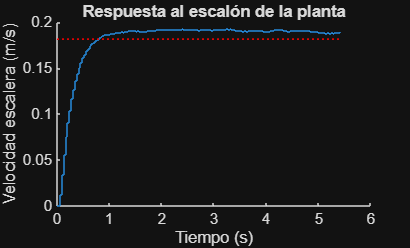


figure
hold on
stairs(t_interes, c_interes)
plot([0 t_fin - t_ini], 0.95*c_inf*[1 1], 'r:')
title("Respuesta al escalón de la planta")
xlabel("Tiempo (s)")
ylabel("Velocidad escalera (m/s)")


fprintf("Modelo de la planta (FdT en m/s/V)")

Modelo de la planta (FdT en m/s/V)

Km = c_inf

Km = 0.1910

tau = -ts/aproximacion

tau = 0.2683


syms s
G = Km/(tau*s + 1);
vpa(G, decimales)

$$ans = \frac{0.191}{0.2683\,s+1.0}$$

**Ejercicio 2**

Corrobore la validez del modelo mediante su simulación en Matlab/Simulink, como  también se hizo en la Práctica 2

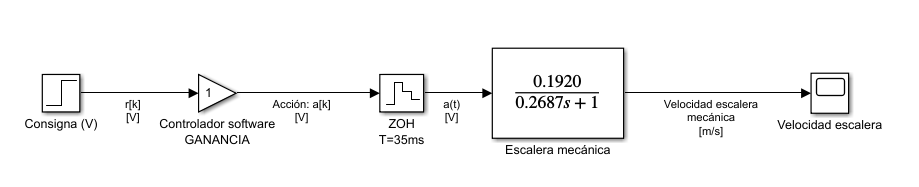

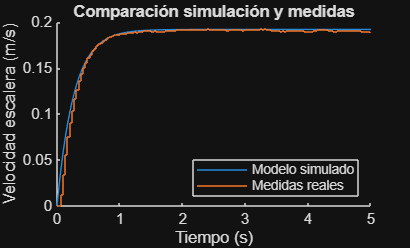

sim_data = load("Fase1/salidaSimulinkEj2");
t_sim = sim_data(:, 1);
c_sim = sim_data(:, 2);

figure
hold on
title("Comparación simulación y medidas")
plot(t_sim, c_sim)
stairs(t_interes, c_interes)
legend('Modelo simulado', 'Medidas reales','Location','southeast')
xlim([0 5])
xlabel("Tiempo (s)")
ylabel("Velocidad escalera (m/s)")

**Ejercicio 3**

Proponga e implemente los siguientes experimentos para caracterizar las alinealidades de  la planta: 

- Para modelar la saturación excite el SM con grandes tensiones 

- Para modelar  la zona muerta excite el SM con pequeñas tensiones. 

Debe de obtener los valores adecuados  con sus unidades de la saturación y zona muerta, explicando el procedimiento de obtención,  y añadir al modelo de Simulink los bloques de las alinealidades caracterizadas  convenientemente colocadas y con coherencia de unidades. 

% Valores obtenidos experimentalmente
fprintf("Saturación de salida (Expresada como módulo máximo de la velocidad de la escalera en m/s). Simétrica.")

Saturación de salida (Expresada como módulo máximo de la velocidad de la escalera en m/s). Simétrica.

c_max_abs = 2.11 % medida lab

c_max_abs = 2.1100


fprintf("Zona muerta. (Expresada como la tensión mínima para que se comience a mover la escalera). Asimétrica")

Zona muerta. (Expresada como la tensión mínima para que se comience a mover la escalera). Asimétrica

deadzone_in_pos = 0.21 % medida lab

deadzone_in_pos = 0.2100

deadzone_out_pos = -0.19 % medida lab

deadzone_out_pos = -0.1900


% Compensación de Km
c_inf_deadzone = 0.1517; % Valor final con la zona muerta y la antigua FdT
km_comp = Km * c_inf/c_inf_deadzone;

fprintf("Nueva aproximación de la planta teniendo en cuenta la zona muerta [m/s/V]")

Nueva aproximación de la planta teniendo en cuenta la zona muerta [m/s/V]

syms s
Gcomp = km_comp/(tau*s + 1);
vpa(Gcomp, decimales)

$$ans = \frac{0.2405}{0.2683\,s+1.0}$$

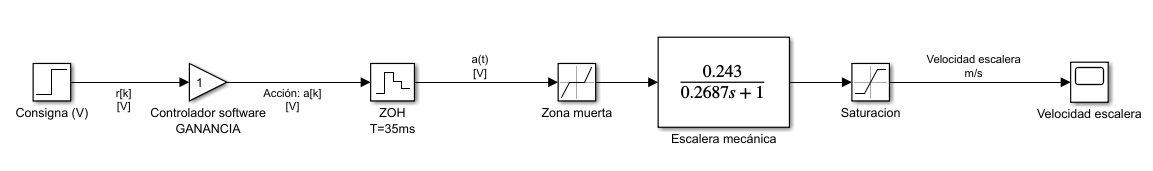

**Ejercicio 4**

Calcule el equivalente discreto de la planta y caracterice teóricamente su respuesta ante  entrada escalón, tanto en régimen permanente como transitorio. 

BoG = c2d(tf(Km, [tau 1]), Ts)


BoG =
 
   0.02336
  ----------
  z - 0.8777
 
Sample time: 0.035 seconds
Discrete-time transfer function.
Model Properties


[~, zp, ~] = zpkdata(BoG, 'v')

zp = 0.8777


fprintf("Valor final ante escalón unitario")

Valor final ante escalón unitario

c_disc_inf = dcgain(BoG) % lim(z->1) BoG = 0.02345 / (1 - 0.8779)

c_disc_inf = 0.1910


fprintf("Tiempo de establecimiento")

Tiempo de establecimiento

ks_disc = ceil(aproximacion / log(abs(zp))) % Aproximación de log(0.05)/log(abs(zp))

ks_disc = 23

ts_disc = Ts * ks_disc

ts_disc = 0.8050

**Ejercicio 5**

Con el número máximo de personas, el escalón unidad no es suficiente para iniciar el movimiento. La perturbación máxima para el valor positivo es de -0.2m/s, valor con módulo superior a la salida frente al escalón unidad (0.192 m/s)

## Fase 2

**Ejercicio 6**

Calcule la FdeT del regulador con sus correspondientes unidades, mediante la aplicación  detallada del método directo, el resultado debe presentarlo de la forma factorizada,  polinomial y con potencias negativas en z. Presente la ecuación en diferencias del  regulador.

clear;

decimales = 5;

decimales = 5


% Planta
Ts=0.035;
Kg = 0.2345;
pg = 0.8779;
aproximacion = -3; %log(0.05)

% Especificaciones deseadas
ts = 0.980;
erpp = 0.03;

fprintf("Parámetros del sistema. Módulo del polo y Km para cada signo")

Parámetros del sistema. Módulo del polo y Km para cada signo

pm_mod = exp(Ts*aproximacion/ts) 

pm_mod = 0.8984

Km_pos = (1 - pm_mod) * (1 - erpp)

Km_pos = 0.1015

Km_neg = (1 + pm_mod) * (1 - erpp)

Km_neg = 1.8965


fprintf("Funciones de transferencia del controlador")

Funciones de transferencia del controlador

syms z
BoG = Kg/(z - pg);
F_pos = (Km_pos * (z - pg)) / (Kg * (z - pm_mod - Km_pos));
F1 = vpa(F_pos, decimales)

$$F1 = \frac{0.1015\,z-0.089108}{0.2345\,z-0.23448}$$

F_neg = (Km_neg * (z - pg)) / (Kg * (z + pm_mod - Km_neg));
F2 = vpa(F_neg, decimales + 1) 

$$F2 = \frac{1.8965\,z-1.66494}{0.2345\,z-0.234055}$$

Solución:


$$F_1(z) = \frac{0.09855z - 0.08652}{0.2345z-0.2338} = \frac{0.4203 - 0.3690\cdot z^{-1}}{1-0.9970\cdot z^{-1}} = 0.4203\cdot\frac{z-0.8779}{z-0.9970}$$



$$c[k] = 0.9970\cdot r[k-1] + 0.4203\cdot r[k] - 0.3690\cdot r[k-1]$$



$$F_2(z) = \frac{1.8414z-1.6166}{0.2345z-0.22114}=\frac{7.8525-6.8938\cdot z^{-1}}{1-0.9430\cdot z^{-1}}=7.8525\cdot\frac{z-0.8779}{z-0.9430}$$



$$c[k] = 0.9430\cdot c[k-1] + 7.8525\cdot r[k] - 6.8938\cdot r[k-1]$$


**Ejercicio 7**

Dibuje una topología (diagrama de bloques) del sistema de acuerdo a las unidades elegidas,  que deberán aparecer indicadas en cada señal o secuencia del dibujo. 

fprintf("Funciones de transferencia del sistema con los reguladores")

Funciones de transferencia del sistema con los reguladores

function res = normalize_to_unit_Z(f, z)
    [num, den] = numden(f);

    coeffs_den = coeffs(den, z);
    z_coeff = coeffs_den(2);
    normalized_num = num / z_coeff;
    normalized_den = den / z_coeff;

    res = vpa(normalized_num / normalized_den, 5);
end

M_pos = normalize_to_unit_Z(simplifyFraction(BoG*F_pos/(1+BoG*F_pos)), z)

$$M\_pos = \frac{0.1015}{z-0.8984}$$

M_neg = normalize_to_unit_Z(simplifyFraction(BoG*F_neg/(1+BoG*F_neg)), z)

$$M\_neg = \frac{1.8965}{z+0.8984}$$

**Ejercicio 8**

Calcule la FdeT del sistema y caracterice teóricamente su salida ante entradas escalón de  ±1 m/s. 

pm_pos = 0.8984;
km_pos = 0.098555;

pm_neg = -0.8984;
km_neg = 1.8414;

% Queda una muestra de más en ts xq se usa la aproximación y por solo tener
% cuatro decimales en el polo. Si se usan todos los decimales o se utiliza
% log(0.05) se obtiene el resultado exacto
fprintf("Caracterización Mpos")

Caracterización Mpos

ts_pos = Ts * ceil(aproximacion/log(abs(pm_pos)))

ts_pos = 1.0150

c_inf_pos = km_pos / (1 - pm_pos)

c_inf_pos = 0.9700

erpp_pos = 1 - c_inf_pos

erpp_pos = 0.0300


fprintf("Caracterización Mneg")

Caracterización Mneg

ts_neg = Ts * ceil(aproximacion/log(abs(pm_neg)))

ts_neg = 1.0150

c_inf_neg = km_neg / (1 - pm_neg)

c_inf_neg = 0.9700

erpp_neg = 1 - c_inf_neg

erpp_neg = 0.0300

**Ejercicio 9**

Calcule en régimen permanente tanto la acción de control como la velocidad de la escalera  subiendo y bajando en diferentes condiciones de carga de la escalera, para consignas de  ±1 m/s. Relacione los incrementos o decrementos de acción de control con el peso de las  personas presentes en la escalera. 

pert_5personas = 0.1;
pert_10personas = 0.2;
entrada = 1;

Aplicando teorema de superposición

M_r_pos = M_pos;
M_p_pos = normalize_to_unit_Z(-1/(1+BoG*F_pos), z)

$$M\_p\_pos = -\frac{1.0\,\left(z-0.9999\right)}{z-0.8984}$$


M_r_neg = M_neg;
M_p_neg = normalize_to_unit_Z(-1/(1+BoG*F_neg), z)

$$M\_p\_neg = -\frac{1.0\,\left(z-0.9981\right)}{z+0.8984}$$


K0_r_pos = round(subs(M_r_pos, z, 1), decimales)

$$K0\_r\_pos = 0.999$$

K0_p_pos = round(subs(M_p_pos, z, 1), decimales)

$$K0\_p\_pos = -0.001$$


K0_r_neg = round(subs(M_r_neg, z, 1), decimales)

$$K0\_r\_neg = 0.999$$

K0_n_neg = round(subs(M_p_neg, z, 1), decimales)

$$K0\_n\_neg = -0.001$$

La perturbación no afecta al tiempo de establecimiento, solo al valor final (y por tanto al error)

K0_ref = subs(M_r_pos, z, 1);
K0_pert= subs(M_p_pos, z, 1);

salida_5personas = round(K0_ref * entrada + K0_pert * pert_5personas, decimales)

$$salida\_5personas = 0.9989$$

erpp_5personas = round((entrada - K0_ref * entrada - K0_pert * pert_5personas)/entrada, decimales)

$$erpp\_5personas = 0.0011$$


salida_10personas = round(K0_ref * entrada + K0_pert * pert_10personas, decimales)

$$salida\_10personas = 0.9988$$

erpp_10personas = round((entrada - K0_ref * entrada - K0_pert * pert_10personas)/entrada, decimales)

$$erpp\_10personas = 0.0012$$

## Fase 3

**Ejercicio 10**